addpath('D:\Git_repos\python\Neuropixel_alignment\src')

data_folder = 'D:\Neuropixel\Verified_data\pt02\';

data_file = [data_folder,'Processed\p_csd_all.mat'];

[ap_output_file, lfp_output_file] = Intarpolate_and_align_AP_2022(data_file);

zscore LFP
LFP Progress: 10%
LFP Progress: 20%
LFP Progress: 30%
LFP Progress: 40%
LFP Progress: 50%
LFP Progress: 60%
LFP Progress: 70%
LFP Progress: 80%
LFP Progress: 90%


ans = 0

LFP Done!
zscore AP
AP Progress: 10%
AP Progress: 20%
AP Progress: 30%
AP Progress: 40%
AP Progress: 50%
AP Progress: 60%
AP Progress: 70%
AP Progress: 80%
AP Progress: 90%
AP Done!


params = load(data_file);

lfp_file = 'D:\Neuropixel\Verified_data\pt02\Raw\file2_g0_t0.imec0.lf.bin'

lfp_file = 'D:\Neuropixel\Verified_data\DBS05\Raw\file2_g0_t0.imec0.lf.bin'

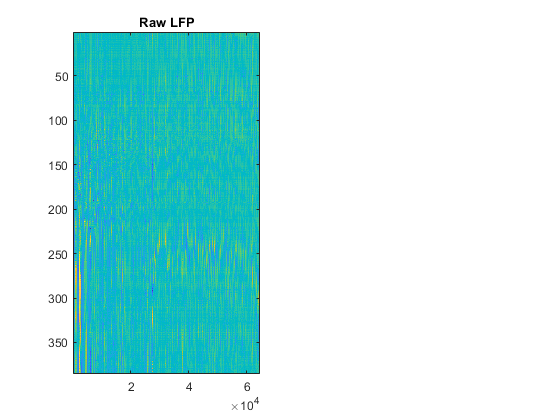

LF_memmap = memmapfile(lfp_file, 'Format',{'int16', [double(params.num_of_raw_channels), length(params.p_csd_lfp_Fs)], 'data'},'Offset', 550002*double(params.num_of_raw_channels)*2);
figure
subplot(1,2,1)
imagesc(LF_memmap.Data.data(:,1:25:end))
title('Raw LFP')



lfp_output_file = 'D:\Neuropixel\Verified_data\pt02\Processed\aligned_AP_to_kilosort\file2_g0_t0.imec0.lf_aligned.bin'

lfp_output_file = 'D:\Neuropixel\Verified_data\DBS05\Processed\aligned_AP_to_kilosort\file2_g0_t0.imec0.lf_aligned.bin'

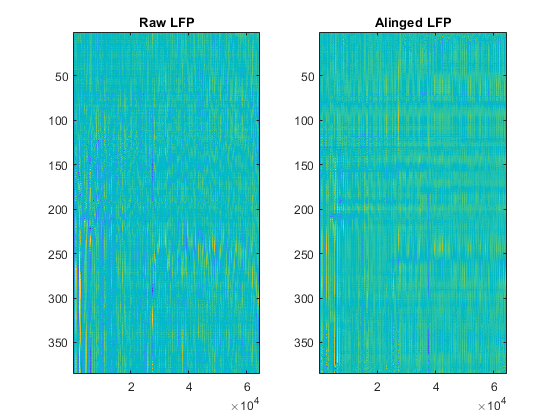

LF_memmap_aligned = memmapfile(lfp_output_file, 'Format',{'int16', [double(params.num_of_raw_channels), length(params.p_csd_lfp_Fs)], 'data'});

subplot(1,2,2)
imagesc(LF_memmap_aligned.Data.data(:,1:25:end))
title('Alinged LFP')